# Least Square

## Practice 2: Estimate representative plane of ground pointcloud

### Problem

In autonomous vehicle, idenfying and removing ground points from the collected pointclouds is important task.

Because we neet to detect and analyze non-ground objects such as vechicles, pedestrian, and buildings within 3D environment.

Design and Solve least squre equation to extract ground point's plane coefficient using equation of plane.

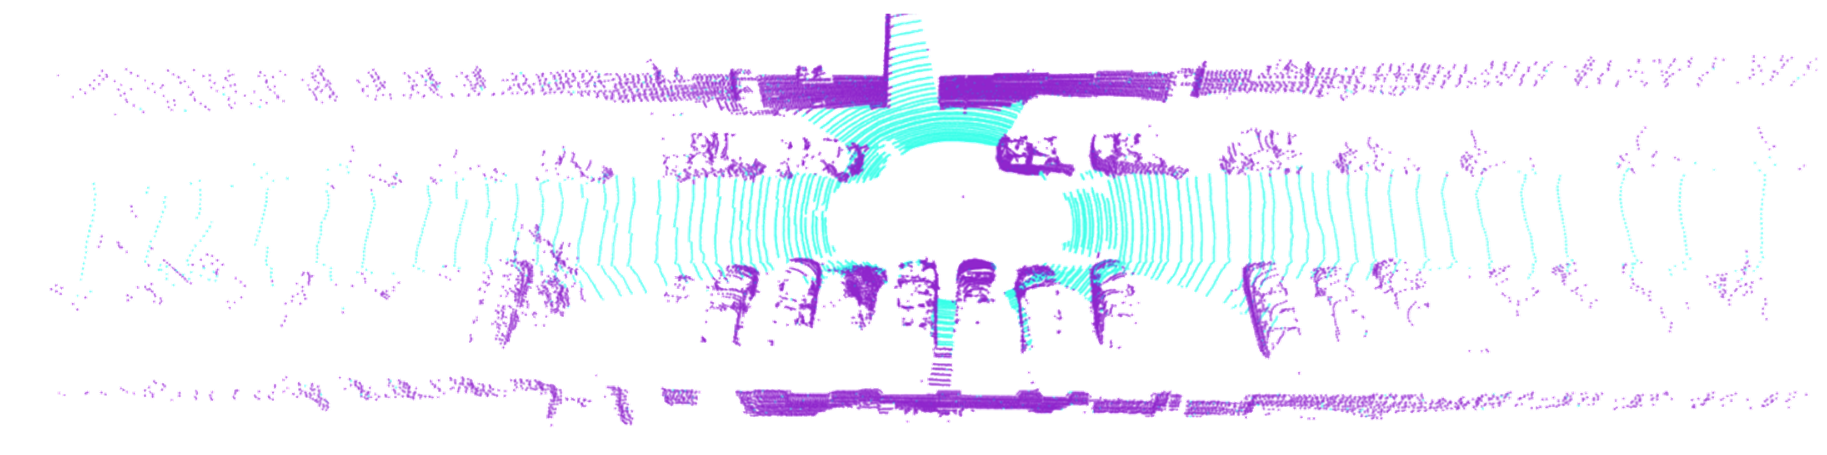

### Data Preprocessing for Ground Extraction & Visualization

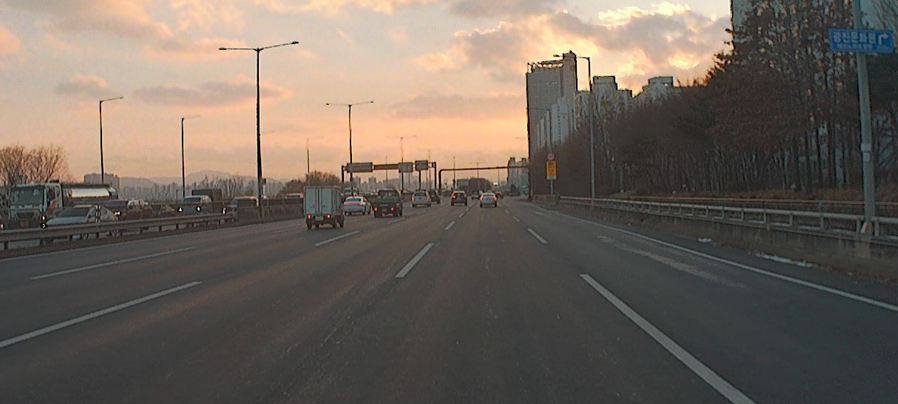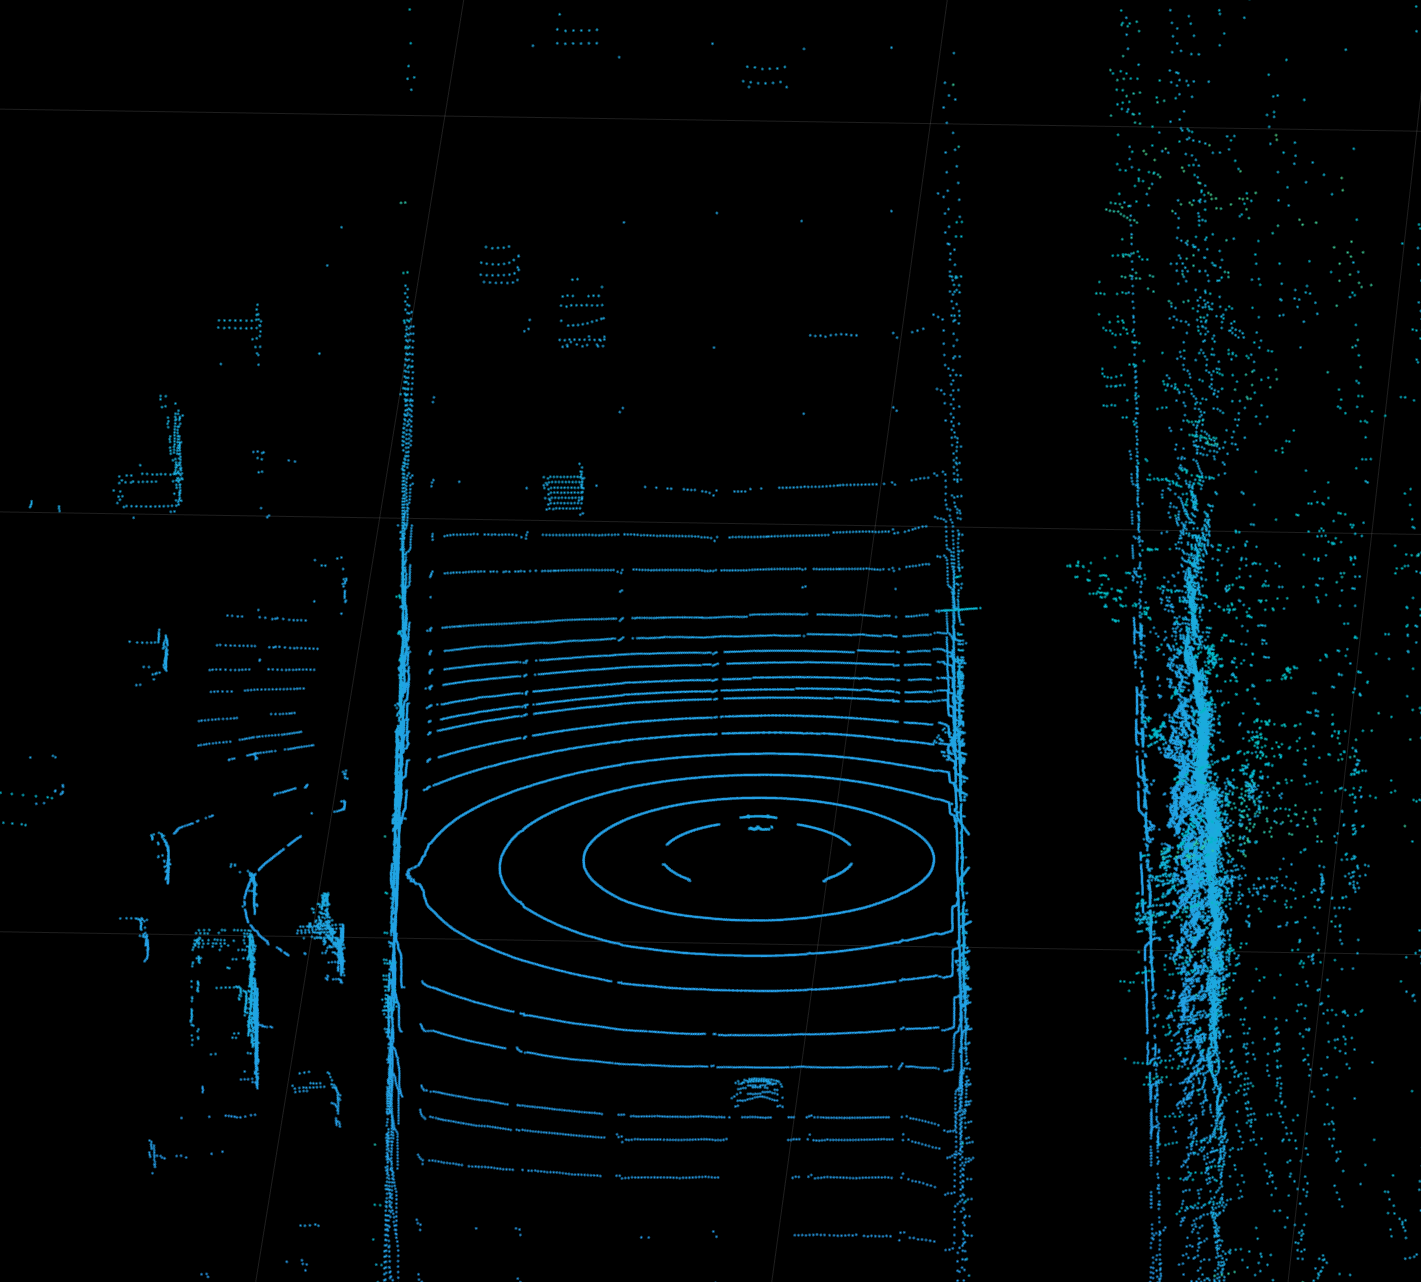

                     **Camera and LiDAR sensor pair data for pointcloud_1.bin**

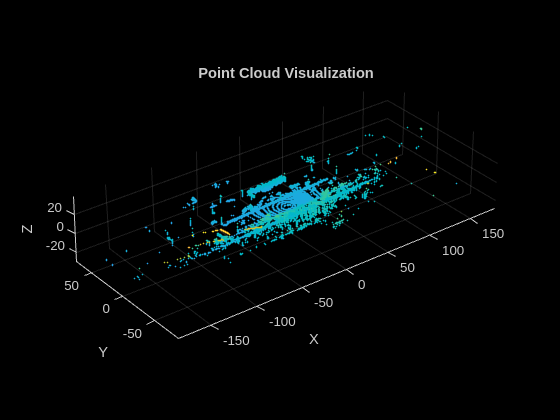

clear; close all;

% Load bin file
filename = "/home/kmw/Downloads/matlabexercise/3_0003_rslidar.bin";
fileID = fopen(filename, 'rb');
data = fread(fileID, 'float');
fclose(fileID);

% one pointcloud is composed of four values: x, y, z, and intensity.
n = length(data) / 4;
if mod(n, 1) ~= 0
    error('The total number of elements in the file is not a multiple of 4.');
end

% Reshape data by grouping 4 values
data = reshape(data, [4, n])';

% Extract only x, y, z data from pointcloud
xyzPoints = data(:, 1:3);

% Visualize pointcloud data acquired from LiDAR sensors
figure;
pcshow(xyzPoints);
title('Point Cloud Visualization');
xlabel('X');
ylabel('Y');
zlabel('Z');

### Extract Ground pointcloud & Visualization

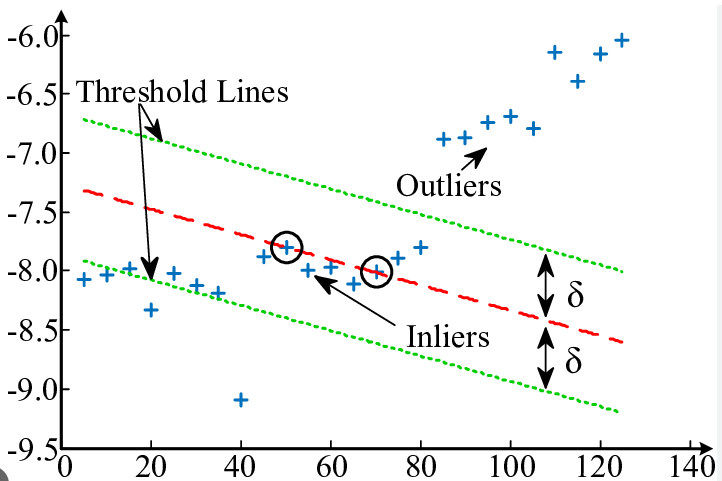

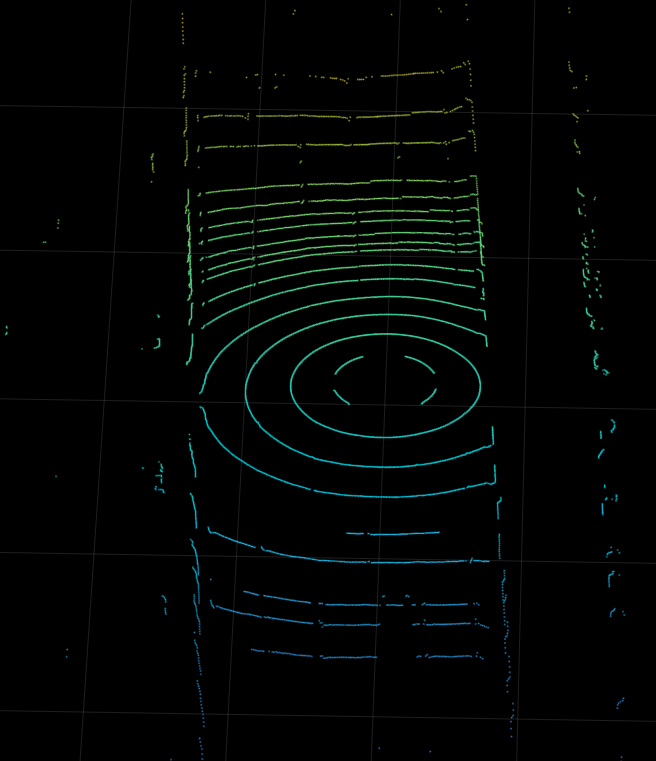

**                 Extract Ground Pointclouds with pcfitplane (RANSAC) algorithm**

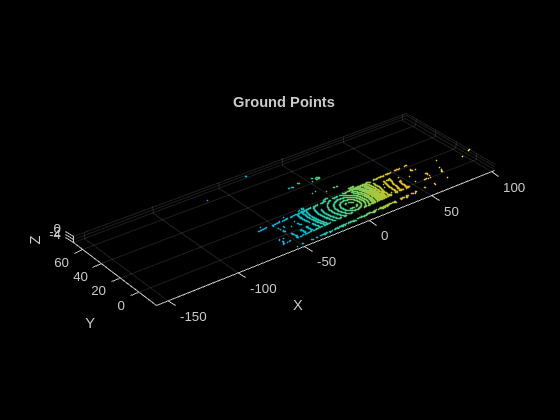

% Convert pointcloud to 'pointCloud' object in MATLAB
ptCloud = pointCloud(xyzPoints);

% Ground extraction using pcfitplane (RANSAC) algorithm
maxDistance = 0.1; % Maximum distance to be included in Ground 
[model, inlierIndices, outlierIndices] = pcfitplane(ptCloud, maxDistance);

% Separate pointclouds that belong to the Grounds and those that do not
groundPoints = select(ptCloud, inlierIndices);
nonGroundPoints = select(ptCloud, outlierIndices);

% Visualization of ground pointclouds
figure;
pcshow(groundPoints);
title('Ground Points');
xlabel('X');
ylabel('Y');
zlabel('Z');

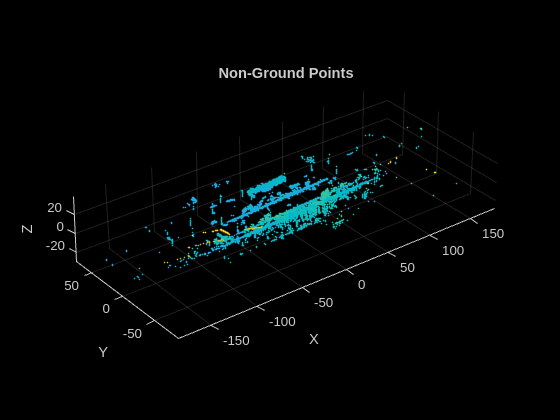


% Visualization of non-ground pointclouds
figure;
pcshow(nonGroundPoints);
title('Non-Ground Points');
xlabel('X');
ylabel('Y');
zlabel('Z');

### Pointcloud Data Preprocessing 

% Extract all point's coordinate from 'pointCloud' object type
xyz = groundPoints.Location;

% Save coordinates of ground pointcloud.
%%%%%%% TODO %%%%%%%
x = xyz(:,1);
y = xyz(:, 2);
z = xyz(:, 3);
%%%%%%%%%%%%%%%%%%%%

### Least square modeling

Find the $\alpha$**, **$\beta$** and **$\gamma$ using real pointcloud data through least square estimation.

A plane equation can be represented as follow (explicit function of plane equation): 

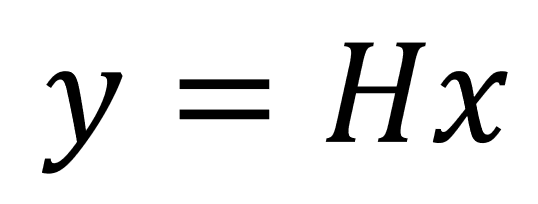

- y: measurement vector

- H: measurement matrix

- x: state vector

% Derive the description of this system! 
%%%%%%% TODO %%%%%%%
Num_of_state = 3; 
H = zeros(length(x), Num_of_state);
Y = zeros(length(z), 1);
%%%%%%%%%%%%%%%%%%%%

% Get H matrix for ground plane
%%%%%%% TODO %%%%%%%
H = [x, y, ones(size(xyz, 1))];
%%%%%%%%%%%%%%%%%%%%

% Get Y vector for ground plane
%%%%%%% TODO %%%%%%%
Y = z;
%%%%%%%%%%%%%%%%%%%%

### Solving least sqaure

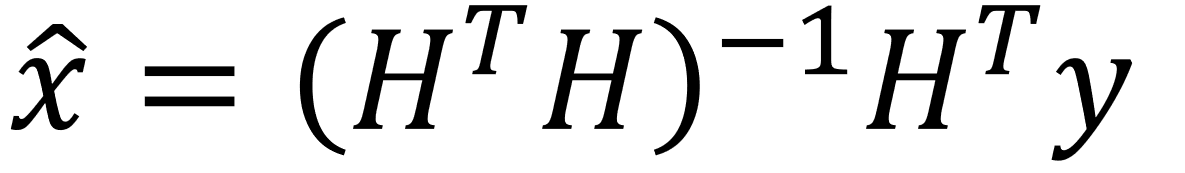

% Calculate least square 
%%%%%%% TODO %%%%%%%
x_estimated = inv(H' * H) * H' * Y;

%%%%%%%%%%%%%%%%%%%%

% Calculate estimated value
%%%%%%% TODO %%%%%%%
y_estimated = H * x_estimated;
%%%%%%%%%%%%%%%%%%%%

### Visualizing with pcshow and mesh

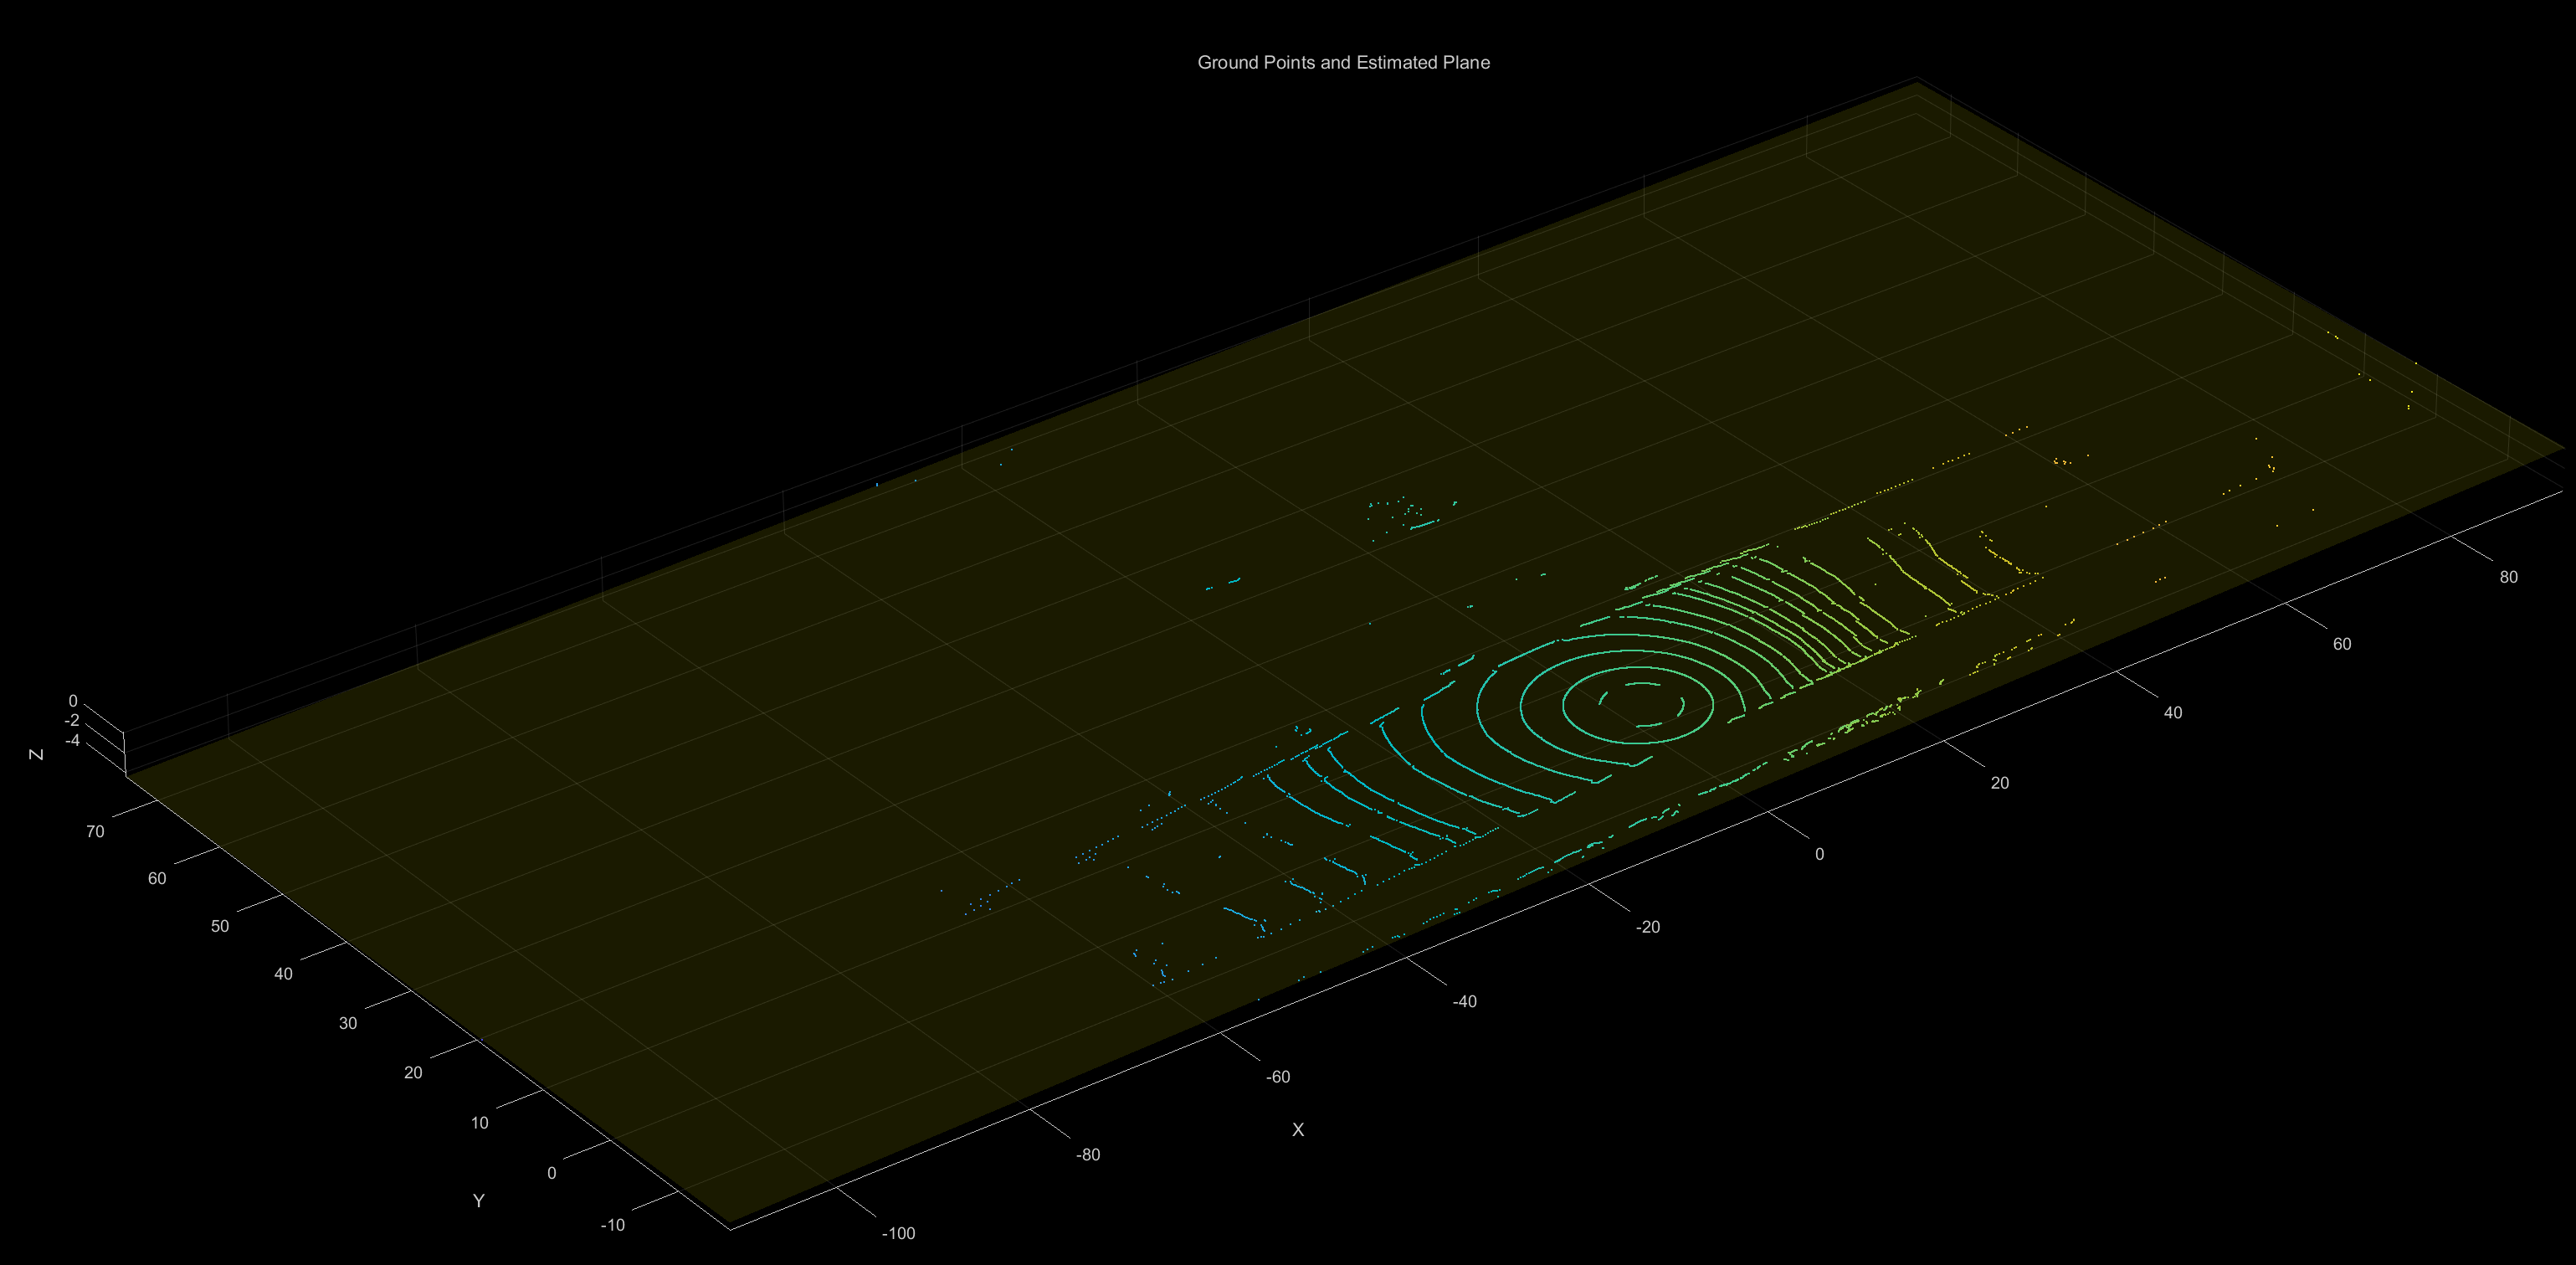

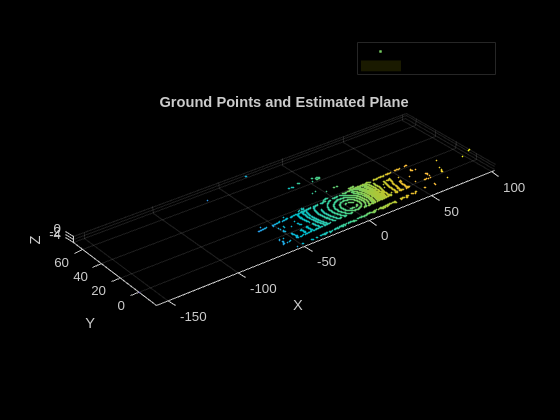

% Visualize the original ground points and the estimated plane
figure;
pcshow(groundPoints);
hold on;
[xGrid, yGrid] = meshgrid(min(x):0.1:max(x), min(y):0.1:max(y));
zGrid = x_estimated(1) * xGrid + x_estimated(2) * yGrid + x_estimated(3);
mesh(xGrid, yGrid, zGrid, 'FaceAlpha', 0.1, 'EdgeColor', 'none', 'FaceColor', 'yellow');
title('Ground Points and Estimated Plane');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend({'Ground Points', 'Estimated Plane'}, 'Location', 'northeast');
hold off;


% Display results
fprintf('Least Squares result \n');

Least Squares result 


fprintf('Estimated plane coefficients: alpha: %f, beta: %f, gamma: %f\n', x_estimated(1), x_estimated(2), x_estimated(3));

Estimated plane coefficients: alpha: NaN, beta: NaN, gamma: NaN


### Visualization with scatter and mesh

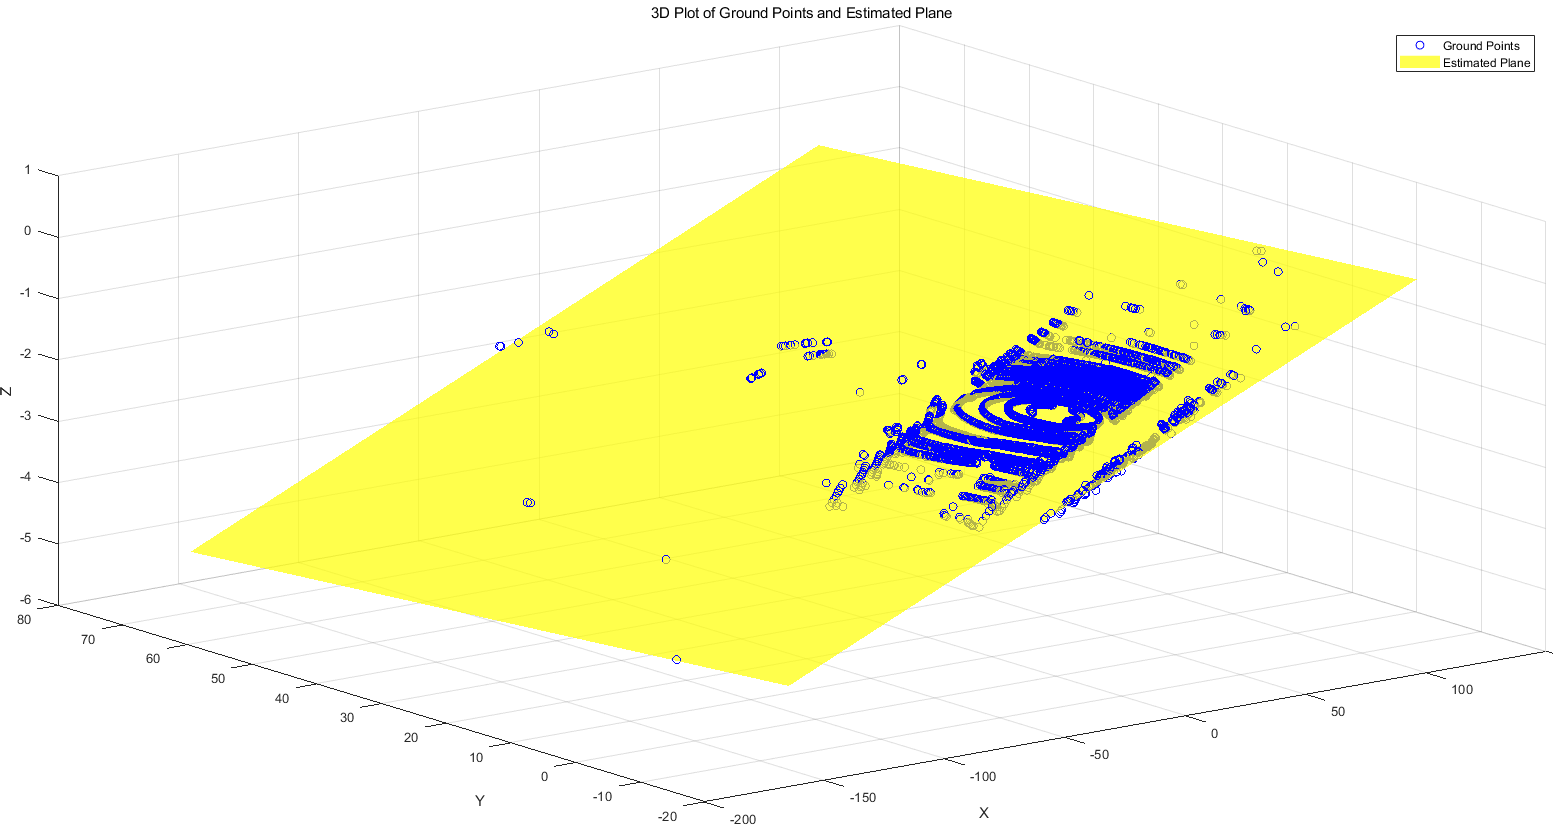

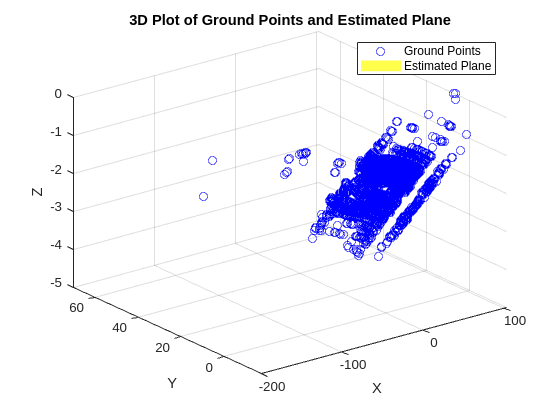

% 3D Plot of X, Y, Z with the estimated plane
figure;
scatter3(x, y, z, 'bo');
hold on;
mesh(xGrid, yGrid, zGrid, 'FaceAlpha', 0.7, 'EdgeColor', 'none', 'FaceColor', 'yellow');
title('3D Plot of Ground Points and Estimated Plane');
xlabel('X');
ylabel('Y');
zlabel('Z');
legend({'Ground Points', 'Estimated Plane'}, 'Location', 'northeast');
hold off;

### Estimate Ground rolling and pitching via Visualization

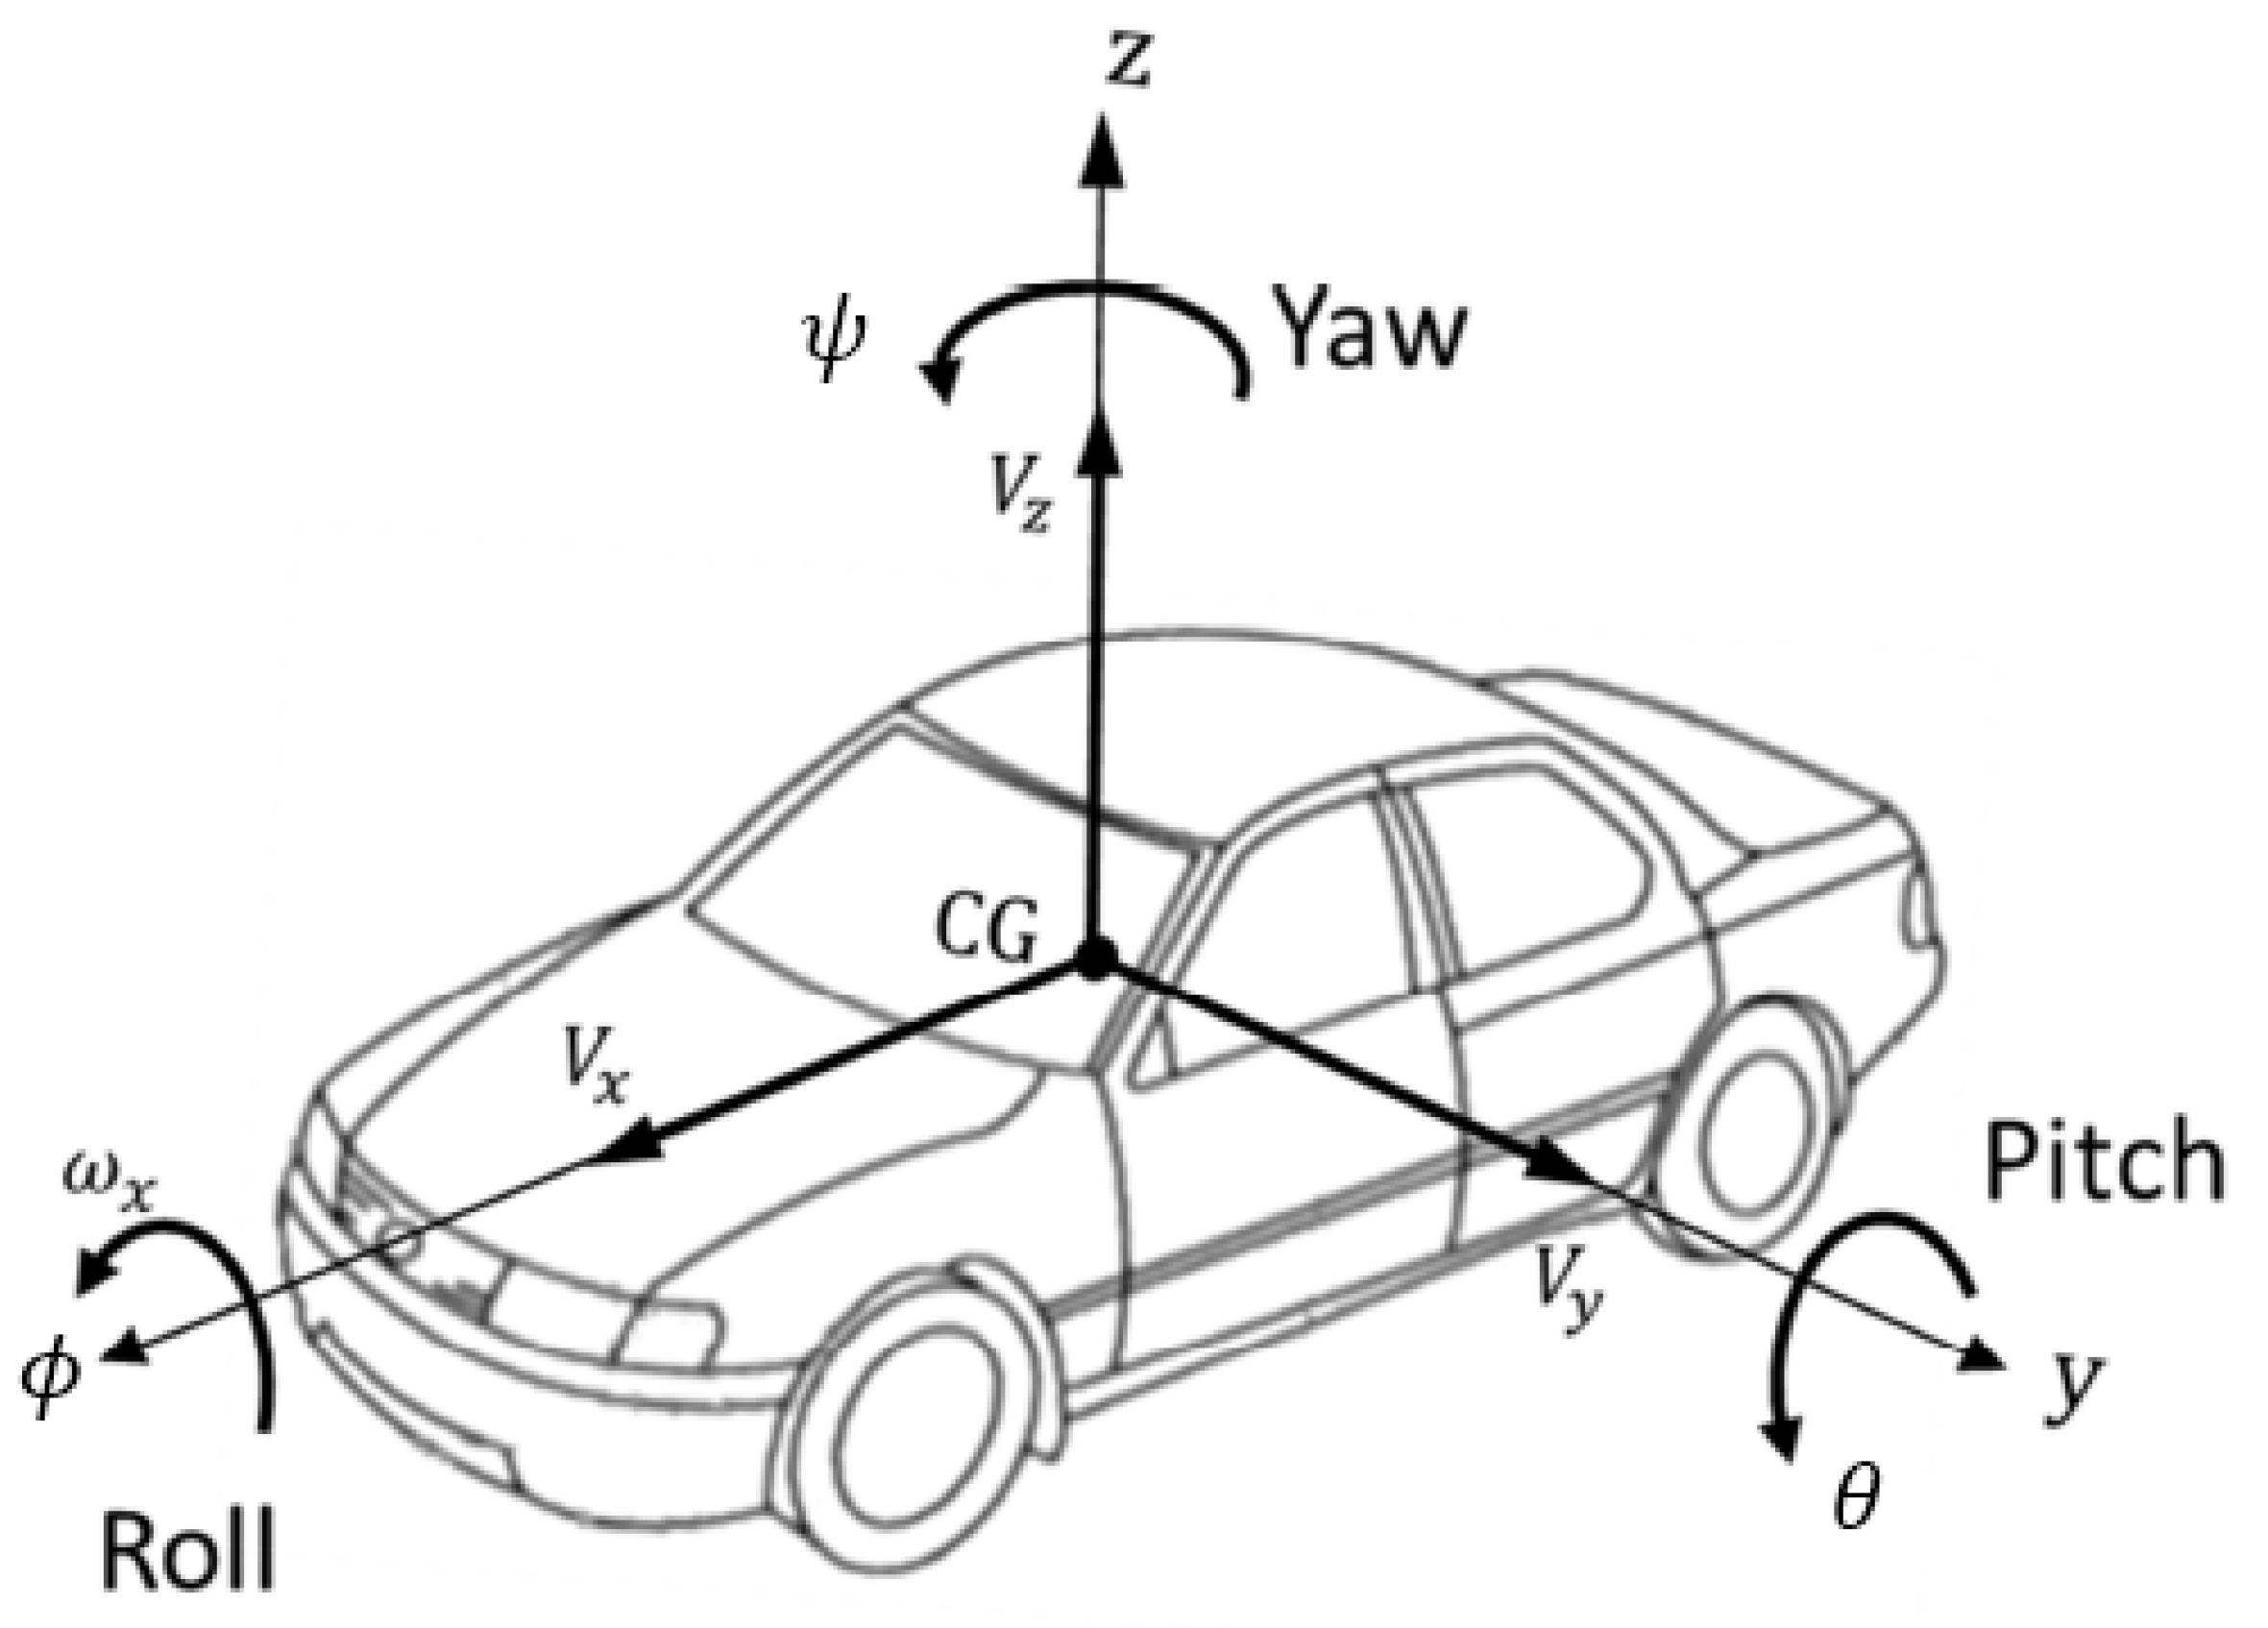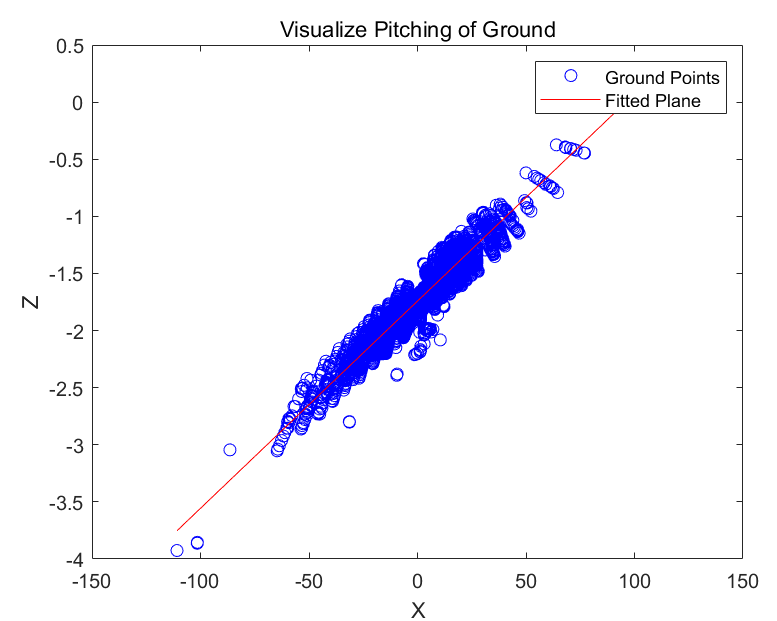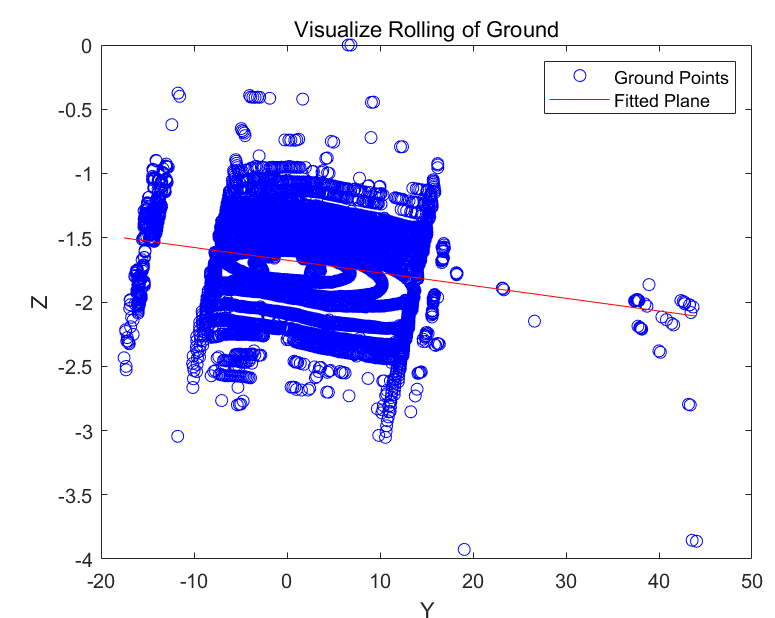

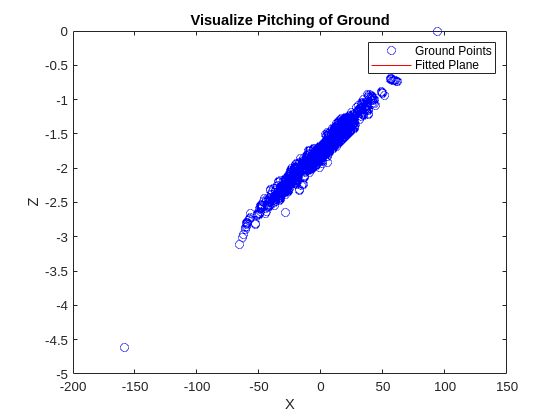

% Plot X vs Z 
figure;
plot(x, z, 'bo');
hold on;
plot(x, x_estimated(1) * x + x_estimated(2) * mean(y) + x_estimated(3), 'r-'); % z = x_estimated(1) + x_estimated(2)*x + x_estimated(3)*mean(y)
title('Visualize Pitching of Ground');
xlabel('X');
ylabel('Z');
legend({'Ground Points', 'Fitted Plane'});
hold off;

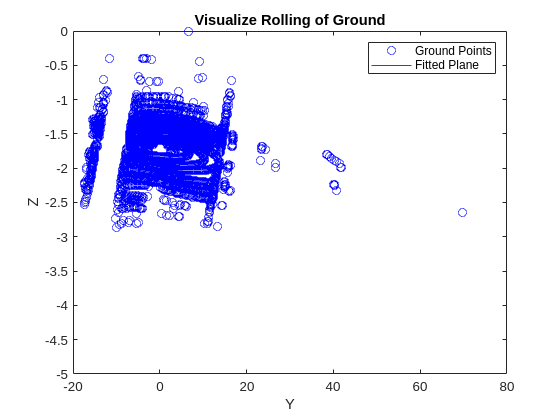


% Plot Y vs Z
figure;
plot(y, z, 'bo');
hold on;
plot(y, x_estimated(1) * mean(x) + x_estimated(2) * y + x_estimated(3), 'r-'); % z = x_estimated(1) + x_estimated(2)*mean(x) + x_estimated(3)*y
title('Visualize Rolling of Ground');
xlabel('Y');
ylabel('Z');
legend({'Ground Points', 'Fitted Plane'});
hold off;